# Using a ResNet for Brain Tumor Classification

## 1. Overview of the Problem: Detecting Tumors Using Neural Networks

**This application of neural networks for tumor detection was adapted from** Ismael, S. A. A., Mohammed, A., & Hefny, H. (2020). An enhanced deep learning approach for brain cancer MRI images classification using residual networks. *Artificial intelligence in medicine*, *102*, 101779.

### Summary

**Computer-Assisted Diagnosis** is a deep learning technology aimed to help doctors and radiologists diagnose and classify tumors using imaging data. While humans are really good at doing this task manually, the process is labor intensive. Approaches to facilitate and automate diagnosis would be decrease healthcare costs and time consumed for manual diagnosis.

This paper used **transfer learning** to train a **Residual Network (ResNet)** to classify three kinds of cancers from MRI images. We will go over the essential parts of transfer learning and a high level overview of what a ResNet does. 

## 2. Preliminary theory

### A. Convolutional Neural Networks

### 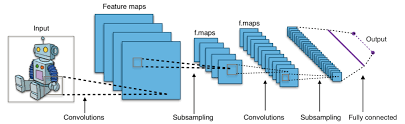

Image taken from [Wikimedia Commons](https://commons.wikimedia.org/wiki/File:Typical_cnn.png)

A **Convolutional Neural Network** consists of several additional layers that perform additional computations that are required to capture spatial information from an image. We'll briefy describe what these layers do.

#### Convolution Layer

An image can be represented as a **tensor**: a multi-dimensional matrix in terms of height, width, and the number of colors. For simplicity, we'll only consider gray-scale images, where there is only 1 color dimension. Thus, the image size is two-dimensional, with a height and width.

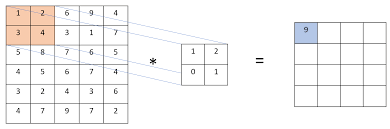

Image taken from [Wikimedia Commons](https://commons.wikimedia.org/wiki/File:Convolution.PNG)

In the convolution layer, we're scanning an image (left matrix) using a **filter** - a smaller matrix (middle) that can capture intrinsic features of the image (think edges, shades, etc). **The objective of the neural network is to learn the best set filters that can be generalized across different images to capture intrinsic data structures.** 

While the image is scanned, the area that is being scanned by the filter is beeing combined through **matrix multiplication**. The resulting matrix is called the** feature map** - a condensed representation of the image (right matrix). 

All together, this entire computational process is called a **convolution**.

#### Pooling Layer

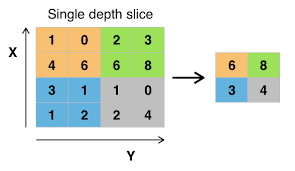

Image taken from [Wikimedia Commons](https://commons.wikimedia.org/wiki/File:Max_pooling.png).

Once we obtain a feature map, the data is condensed even further in the **pooling layer. **The purpose of the pooling layer is to **reduce the computational costs** downstream and **perform feature extraction** for the most important features in an image.   

#### Activation Layer: Rectified Linear Units (ReLUs)

We have seem what the sigmoid activation function does - it transforms data into the range of [0, 1], corresponding to probabilities. Now we will consider a new function: the **Rectified Linear Unit (ReLU)**.

The ReLU floors values to be 0 if the value is negative, or to be that value if positive. A plot of the ReLU distribution is shown below.

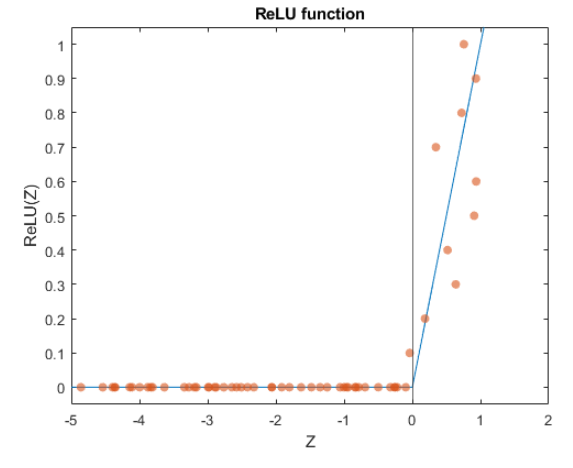

**There are several reasons why the ReLU performs well in neural networks**:

- The gradient during backpropagation is not saturated with a ReLU.

- The ReLU introduces sparsity and is a simple operation to perform, decreasing computational overhead.

#### Fully Connected Layer

From here, we perform a feedforward neural network computation. A schematic of the computation is shown below for review.

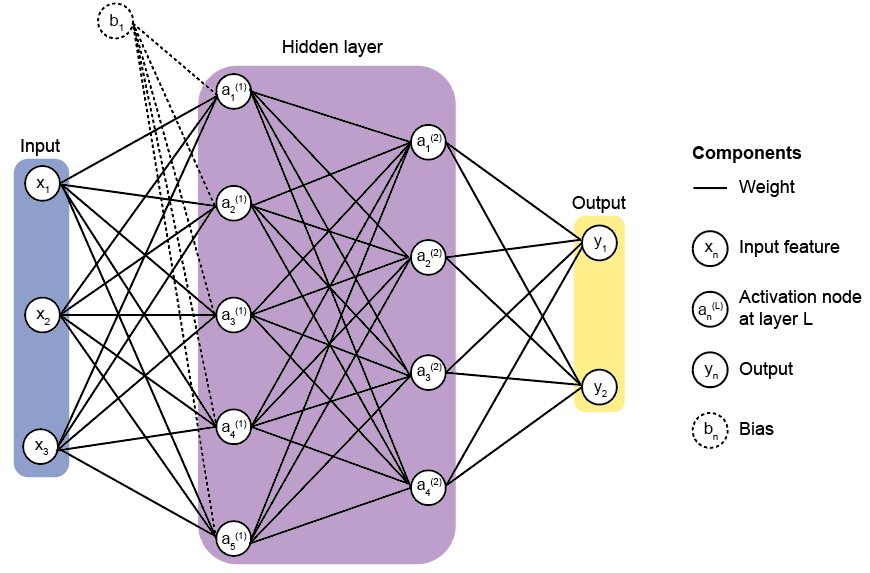

#### Loss Layer 

### B. Transfer learning

### C. Residual Networks

### D. Data Augmentation

## Load data

% Clear workspace
clear all
 
% Images Datapath – Please modify your path accordingly 
datapath='D:/Data/Brain_img/dataset';
 
% Image Datastore
imds = fileDatastore(fullfile(datapath), ...
                   'ReadFcn', @load, ...
                   'FileExtensions','.mat');
for i = 1:length(imds.Files)
    data.(i) = read(imds.Files(i));
end
read(imds)

% Determine the split up
total_split=countEachLabel(imds)

## Visualize images

% Number of Images
num_images=length(imds.Labels);

% Visualize random images
perm=randperm(num_images,6);
figure;
for idx=1:length(perm)
    
    subplot(2,3,idx);
    imshow(imread(imds.Files{perm(idx)}));
    title(sprintf('%s',imds.Labels(perm(idx))))
    
end

## Training a ResNet using transfer learning

Now we'll implement transfer learning using the ResNet50 model. We'll replace the fully connected layer at the head of the model - this contains all the fine-tuning weights that are specific for a given task.

### A. Preprocess training and test data

First, we'll create a training and validation set.

% Preprocessing Technique
imdsTrain.ReadFcn = @(filename)preprocess_Xray(filename);
imdsTest.ReadFcn = @(filename)preprocess_Xray(filename);

% Number of categories
numClasses = numel(categories(imdsTrain.Labels));

% Actual Labels
ground_truth = imds.Labels;

### B. Loading the ResNet50 model

Now let's load the model.

% ResNet Architecture  
net = resnet50;
CANCER_MDL = layerGraph(net);
clear net;

### C. Create new layers for transfer learning.

The layers we have to replace include:

- The fully connected layer

- The softmax layer

- The classification layer

% Fully connected layer
MRI_FC_LAYER    = fullyConnectedLayer(numClasses, ...
                                      'Name', 'MRI_FC', ...
                                      'WeightLearnRateFactor', 10, ...
                                      'BiasLearnRateFactor',10);
CANCER_MDL      = replaceLayer(CANCER_MDL, 'fc1000', MRI_FC_LAYER);

% Softmax layer
MRI_SOFTMAX     = softmaxLayer('Name','MRI_Softmax');
CANCER_MDL      = replaceLayer(CANCER_MDL, 'fc1000_softmax', MRI_SOFTMAX);

% Classification layer
MRI_CLASSIFY   = classificationLayer('Name', 'CANCER_CLASSIFIER');
CANCER_MDL      = replaceLayer(CANCER_MDL, 'ClassificationLayer_fc1000', MRI_CLASSIFY);

### D. Specify model hyperparameters

Now let's specify some model hyperparameters.

% Training Options, we choose a small mini-batch size due to limited images 
options = trainingOptions(...
                          'adam',...                     % ADAM Optimization
                          'MaxEpochs', 30, ...           % Number of epochs without early stopping
                          'MiniBatchSize', 8,...         % Mini-batches (don't worry about it)
                          'Shuffle','every-epoch', ...   % Shuffling data 
                          'InitialLearnRate', 1e-4, ...  % Initial learning rate - related to ADAM
                          'Verbose', true, ...           % Show warnings if any
                          'Plots','training-progress');  % Show model progress

### E. Data augmentation

Now let's perform data augmentation. We'll introduce rotation, reflections, and shearing.

Let's create a method that will perform this for us.

% Data Augumentation
augmenter = imageDataAugmenter(...
                               'RandRotation', [-5 5], ...
                               'RandXReflection', 1, ...
                               'RandYReflection', 1, ...
                               'RandXShear', [-0.05 0.05], ...
                               'RandYShear', [-0.05 0.05]);

Now let's augment the training images. We'll also force the image size to be 224 x 224, which is necessary for ResNet50.

IMG_DIM       = [224, 224]
augTrainData  = augmentedImageDatastore(IMG_DIM, ...
                                  imdsTrain, ...
                                  'DataAugmentation', augmenter);
augTestData   = augmentedImageDatastore(IMG_DIM, ...
                                        imdsTest);

### F. Model training

Now that we've set up the model and the data, let's train the new model.

% Training
[MRI_ResNet, trainingInfo] = trainNetwork(augTrainData, CANCER_MDL, options);

Once the model has been trained, we'll classify the labels.

[predicted_labels, posterior] = classify(netTransfer, augTestData);

### G. Validation

Let's visualize the results using a confusion matrix.

figure;
plotconfusion(actual_labels, predicted_labels')
title('MRI ResNet50 confusion matrix');

## Summary